# Import, Visualize, and Partition Molecular Datasets

### Introduction

This example illustrates the integration of [Python-MATLAB](https://www.mathworks.com/help/matlab/call-python-libraries.html) for molecular data processing and analysis, specifically focusing on [Lipophilicity](https://www.sciencedirect.com/topics/biochemistry-genetics-and-molecular-biology/lipophilicity) and [Aqueous Solubility](https://www.sciencedirect.com/topics/biochemistry-genetics-and-molecular-biology/solubility) data. These parameters are crucial in molecular design and drug discovery, as they significantly impact a compound's pharmacokinetics and bioavailability. By understanding and optimizing these properties, one can enhance a drug's therapeutic efficacy through improved absorption, distribution, and interaction with biological targets.

In this example, we demonstrate how to import a database containing such data in [.csv](https://www.mathworks.com/help/matlab/ref/csvread.html) format. The data, as reported in [1], can be accessed via the  [link](https://zenodo.org/records/5137613#.YQortyWxVhG) provided in the referenced paper. 

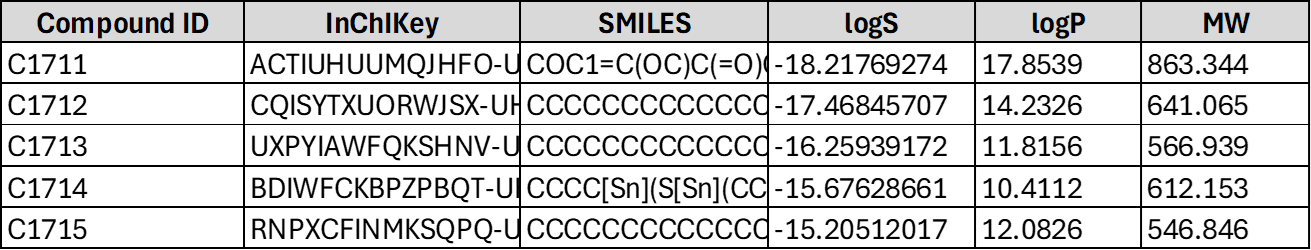

The example also showcases how to visualize any selected molecule from the loaded database, along with its corresponding LogP and LogS values. Subsequently, the database is partitioned based on the normalized LogP and LogS values as follows

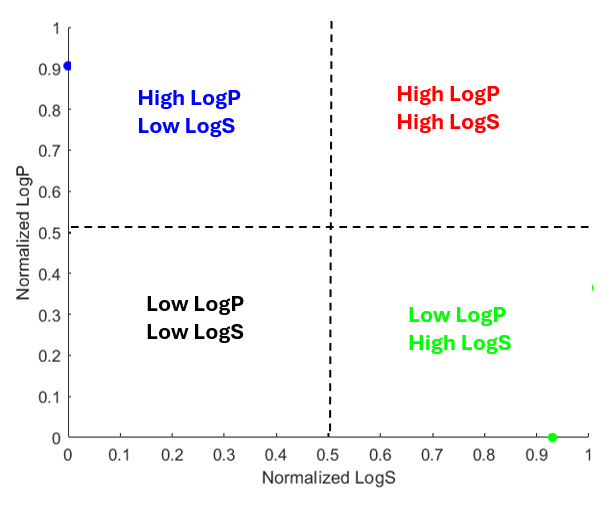

### Requirements

- [Python](https://www.python.org/)

- [RDKit](https://www.rdkit.org/) Open-Source Cheminformatics Software

#### Install Python 

Set up your Python environment by following the instructions provided in the guide found at [Python](https://www.python.org/downloads/release/python-3110/) webpage. Make sure to give the python address and to check versions of Python compatible with MATLAB products by release. This allows to build proper [MATLAB Interface to Python](https://www.mathworks.com/support/requirements/python-compatibility.html). 

% Set path to Python.exe
pythonExecutable = 'C:\Users\...\AppData\Local\Programs\Python\Python311/python.exe'; % Update this path

% Set the Python.exe in MATLAB
pyenv('Version', pythonExecutable);

% Verify Python config
disp('Python version:');

Python version:


pyversion;


       version: '3.11'
    executable: 'C:\Users\hjooya\AppData\Local\Programs\Python\Python311\python.exe'
       library: 'C:\Users\hjooya\AppData\Local\Programs\Python\Python311\python311.dll'
          home: 'C:\Users\hjooya\AppData\Local\Programs\Python\Python311'
      isloaded: 1



warning('off','all')

#### Install RDKit

This example uses some of the functions from RDKit. It can be installed easily by following its [installation](https://www.rdkit.org/docs/Install.html) instructions on Linux, Windows, and macOS. You can install RDKit using pip.

### Import a csv file

We use MATLAB [readtable](https://www.mathworks.com/help/matlab/ref/readtable.html) function that creates a table by reading column-oriented data from a text file, spreadsheet (including Microsoft® Excel®) file, XML file, HTML file, or a Microsoft Word document. `readtable` detects elements of your data, such as delimiter and data types, to determine how to import your data.

data = readtable('LogP_LogS.csv');

In order to show how many molecules we have in the dataset, we use [height](https://www.mathworks.com/help/matlab/ref/height.html) function that returns the number of rows in the table.

numRows = height(data);
fprintf('This data file has %d molecules.\n', numRows);

This data file has 9943 molecules.


### Extract Data

A table is a container that stores column-oriented data in variables. To access the data in a table, you can index into the table by specifying rows and variables, just as you can index into a matrix by specifying rows and columns. You can learn more in this page: [Access Data in Tables](https://www.mathworks.com/help/matlab/matlab_prog/access-data-in-a-table.html).

 smilesList = data.SMILES;
 LogS = data.logS;
 LogP = data.logP;
 MW = data.MW;

### Visualize a sample molecule

You can pick any row to look at

% Pick a sample row number
N_Row = 320;

% Check if the input is valid
if N_Row < 1 || N_Row > numRows
    error('Invalid row number. Please enter a number between 1 and %d.', numRows);
end

% Get the SMILES string for the selected row
sampleSMILES = smilesList{N_Row}

sampleSMILES = 'CN(CCCN1c2ccccc2Sc2c1cc(cc2)C(C)(C)C)C.Cl'

LogS_data = LogS(N_Row)

LogS_data = -7.3536

LogP_data = LogP(N_Row)

LogP_data = 6.4055

The "*RDKitDraw.m*" is a custom-built function that uses RDKit functionality to draw the selected SMILES. Learn more about this function in our **previous example**.

Python version:

       version: '3.11'
    executable: 'C:\Users\hjooya\AppData\Local\Programs\Python\Python311\python.exe'
       library: 'C:\Users\hjooya\AppData\Local\Programs\Python\Python311\python311.dll'
          home: 'C:\Users\hjooya\AppData\Local\Programs\Python\Python311'
      isloaded: 1

RDKit successfully imported in MATLAB.


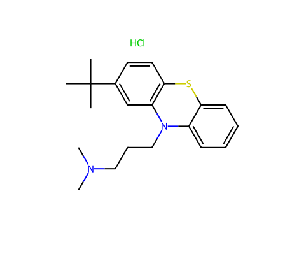

RDKitDraw(pythonExecutable, sampleSMILES,N_Row);

### Partition the database by LogP and LogS values

"*LogP_LogS_Partition*" is a simple custom-built function that normalizes the LogP and LogS values and uses the following simple to partition them. 

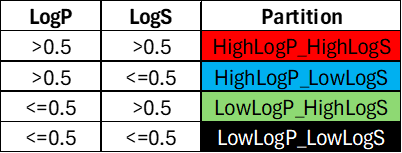

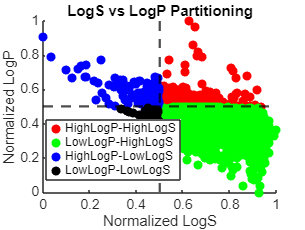

% Call the LogP_LogS_Partition function
folderPath = pwd;
fileName = 'LogP_LogS.csv';

[X, Y, labels] = LogP_LogS_Partition(folderPath, fileName);

You can count the number of molecules in each partition.

% Calculate and print the number of molecules in each group
numHighLogP_HighLogS = sum(labels == "HighLogP-HighLogS");
numLowLogP_HighLogS = sum(labels == "LowLogP-HighLogS");
numHighLogP_LowLogS = sum(labels == "HighLogP-LowLogS");
numLowLogP_LowLogS = sum(labels == "LowLogP-LowLogS");

fprintf('Number of molecules in each group:\n');

Number of molecules in each group:


fprintf('HighLogP-HighLogS: %d\n', numHighLogP_HighLogS);

HighLogP-HighLogS: 908


fprintf('LowLogP-HighLogS: %d\n', numLowLogP_HighLogS);

LowLogP-HighLogS: 8856


fprintf('HighLogP-LowLogS: %d\n', numHighLogP_LowLogS);

HighLogP-LowLogS: 141


fprintf('LowLogP-LowLogS: %d\n', numLowLogP_LowLogS);

LowLogP-LowLogS: 38


Let's double check and make sure that no molecule is left out, by comparing the sum of the number of molecules in all 4 partitions with the total number of molecules in the original dataset.

% Sum up all the numbers from each group
totalMolecules = numHighLogP_HighLogS + numLowLogP_HighLogS + numHighLogP_LowLogS + numLowLogP_LowLogS;

% Read the original data
data = readtable(fullfile(folderPath, fileName));

% Verify the total number of molecules
originalMoleculeCount = height(data);
if totalMolecules == originalMoleculeCount
    fprintf('The sum of all groups (%d) matches the total number of molecules in the original file (%d).\n', totalMolecules, originalMoleculeCount);
else
    fprintf('Mismatch in total molecule count! Sum of groups: %d, Original count: %d\n', totalMolecules, originalMoleculeCount);
end

The sum of all groups (9943) matches the total number of molecules in the original file (9943).


Finally, you can save each partition into a separate file for further analysis.

% Generate CSV files for each partition
writetable(data(labels == "HighLogP-HighLogS", :), fullfile(folderPath, 'HighLogP-HighLogS.csv'));
writetable(data(labels == "LowLogP-HighLogS", :), fullfile(folderPath, 'LowLogP-HighLogS.csv'));
writetable(data(labels == "HighLogP-LowLogS", :), fullfile(folderPath, 'HighLogP-LowLogS.csv'));
writetable(data(labels == "LowLogP-LowLogS", :), fullfile(folderPath, 'LowLogP-LowLogS.csv'));

### Exercises

- **Investigate Correlation:** Is there a correlation between the similarities in molecular structures and their corresponding LogP and LogS values?

- **Analyze Partitioned Data:** Load each of the newly saved partitioned datasets and visualize 10 sample molecules from each one. Do you observe any similarities among them?

### References

[1] Oliver Wieder, *et. al*., "Improved Lipophilicity and Aqueous Solubility Prediction with Composite Graph Neural Networks", Molecules 2021, 26, 6185.